## Pré-processamento das imagens

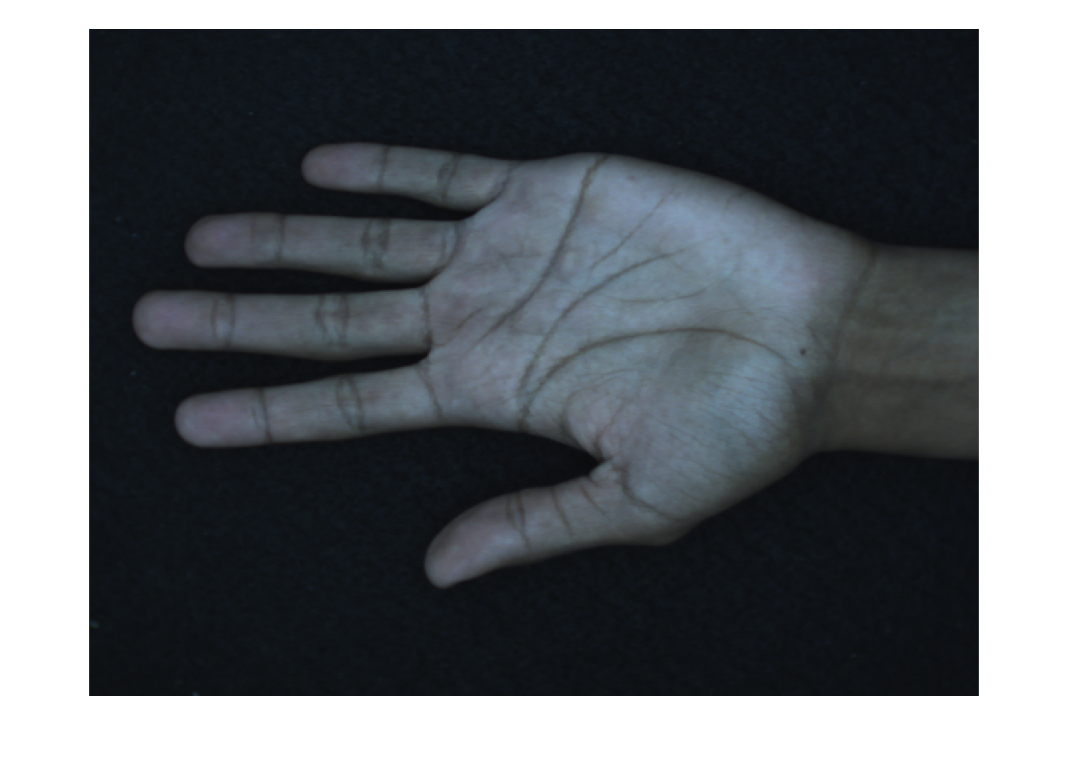

% clear; clc;

imagem = imread('..\Dataset\85\13_L_V_H_P_2.tif');

montage({imagem})

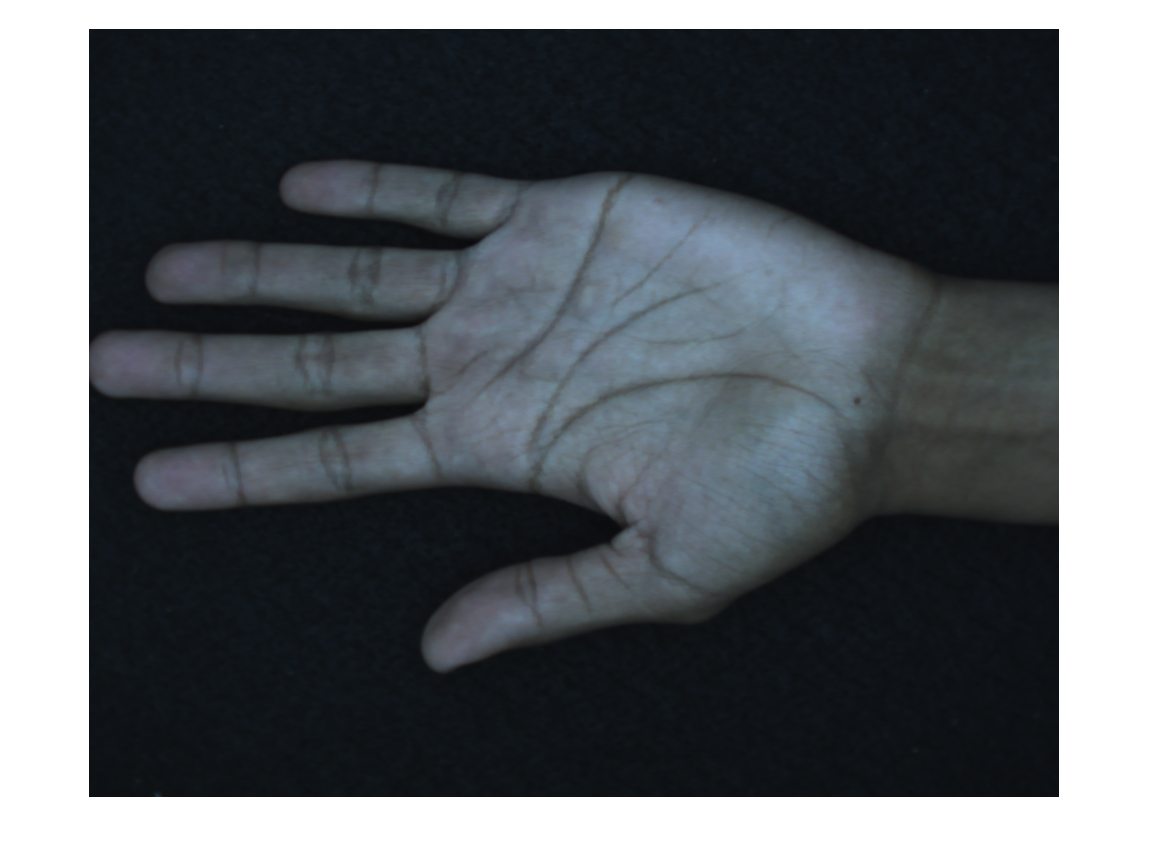

for x = 1:size(imagem,2)
    if sum(imagem(192:576, x, 1) > 70) > 10 || sum(imagem(192:576, x, 2) > 70) > 10 || sum(imagem(192:576, x, 3) > 70) > 10
        xMaoDedos = x;
        break
    end
end
imagemCropDedos = imagem(:, xMaoDedos:size(imagem,2), :);

imshow(imagemCropDedos);

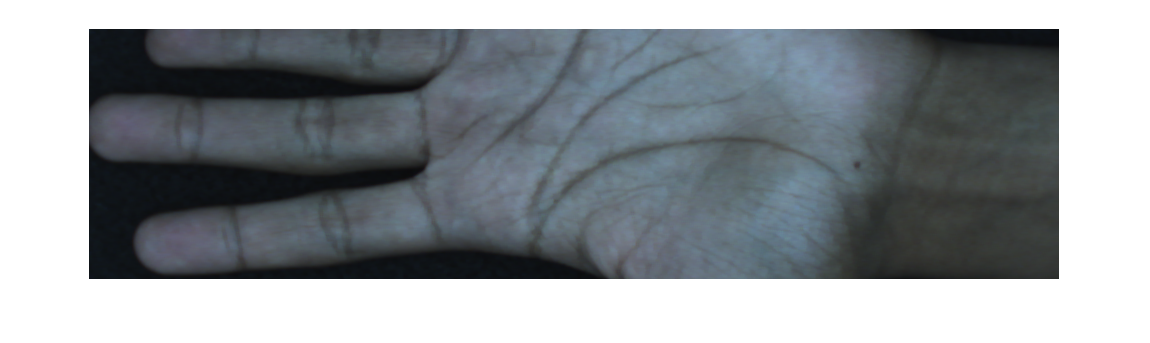


for y = 1:size(imagemCropDedos,1)
    if imagemCropDedos(y, size(imagemCropDedos,2)-150, 1) > 45 || imagemCropDedos(y, size(imagemCropDedos,2)-150, 2) > 45 || imagemCropDedos(y, size(imagemCropDedos,2)-150, 3) > 45
        yMaoSuperior = y;
        break
    end
end
for y = size(imagemCropDedos,1):-1:1
    if imagemCropDedos(y, size(imagemCropDedos,2)-10, 1) > 45 || imagemCropDedos(y, size(imagemCropDedos,2)-10, 2) > 45 || imagemCropDedos(y, size(imagemCropDedos,2)-10, 3) > 45
        yMaoInferior = y;
        break
    end
end
imagemCrop = imagemCropDedos(yMaoSuperior:yMaoInferior, :, :);

imshow(imagemCrop);

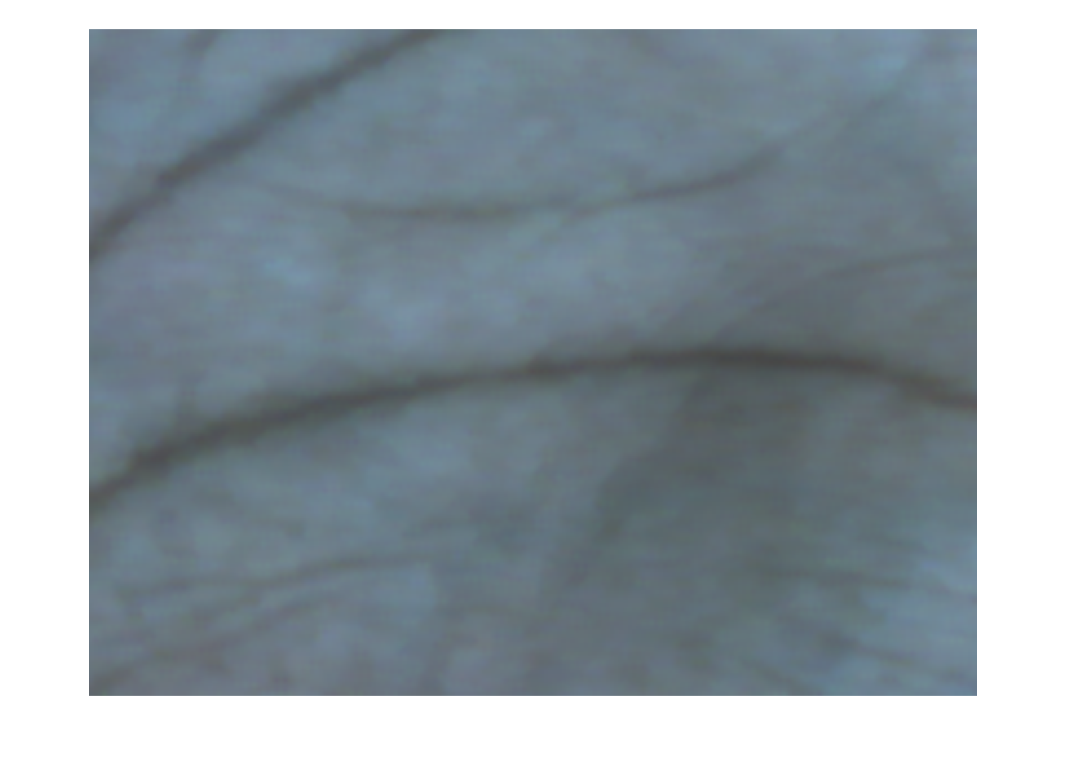

centroid = [fix(0.45*size(imagemCrop,1)), fix(0.62*size(imagemCrop,2))];
d1 = 75;
d2 = 100;

E1 = (centroid(1) - d1):(centroid(1) + d1);
E2 = (centroid(2) - d2):(centroid(2) + d2);

% ROI = imagemCrop;
% ROI(E1, E2, :) = 0;
ROI = imagemCrop(E1,E2,:);

montage({ROI})

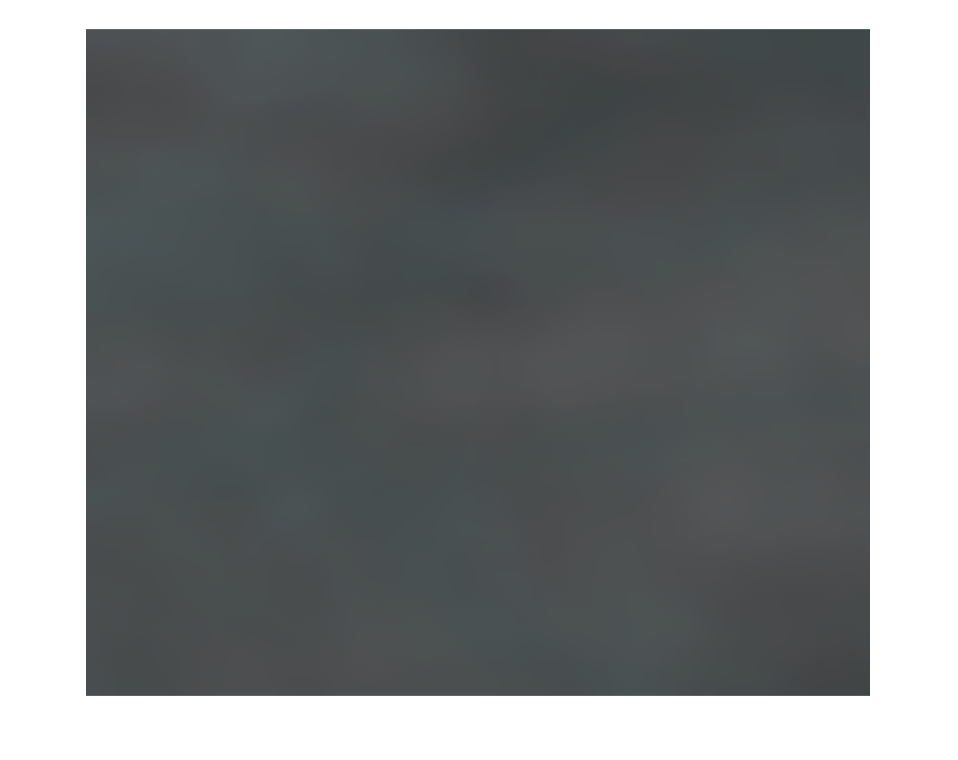

ROI_filtered = medfilt3(ROI, [15,15,3],'symmetric');
montage({ROI_filtered})

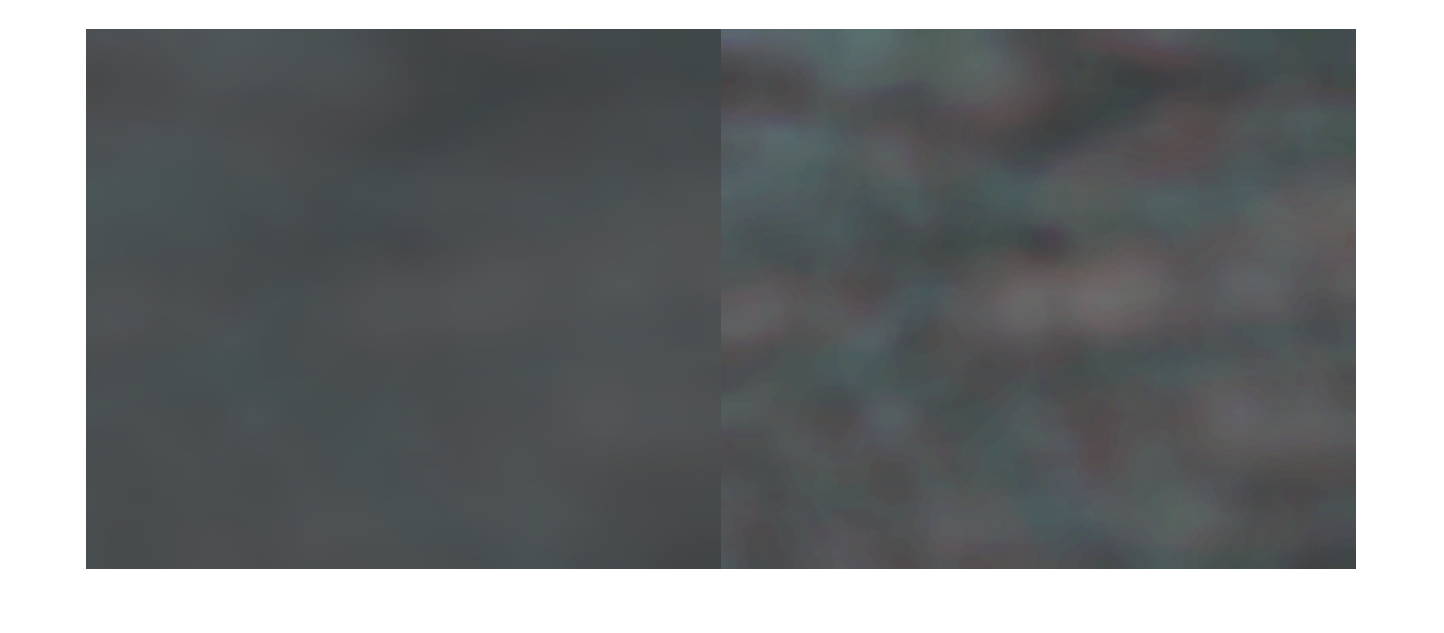

adaptHistEqualR = adapthisteq(ROI_filtered(:,:,1));
adaptHistEqualG = adapthisteq(ROI_filtered(:,:,2));
adaptHistEqualB = adapthisteq(ROI_filtered(:,:,3));

adaptHistEqualRGB(:,:,1) = adaptHistEqualR;
adaptHistEqualRGB(:,:,2) = adaptHistEqualG;
adaptHistEqualRGB(:,:,3) = adaptHistEqualB;

montage({ROI_filtered, adaptHistEqualRGB})

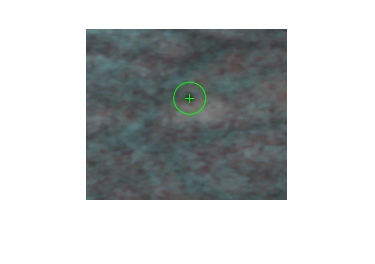

points = detectSURFFeatures(adaptHistEqualRGB(:,:,3));
imshow(adaptHistEqualRGB); hold on;
plot(points);

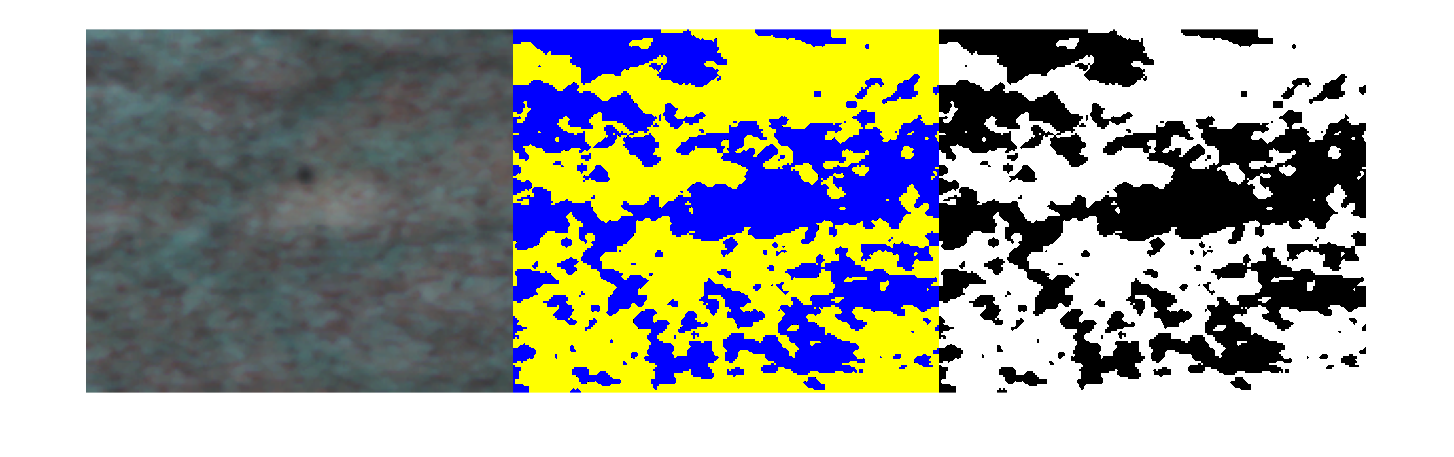

L = imsegkmeans(adaptHistEqualRGB,2);
B = labeloverlay(adaptHistEqualRGB,L);

img = imbinarize(B);
imgBinarize1 = img(:,:,1);
montage({adaptHistEqualRGB, img, imgBinarize1}, 'Size', [1,3])

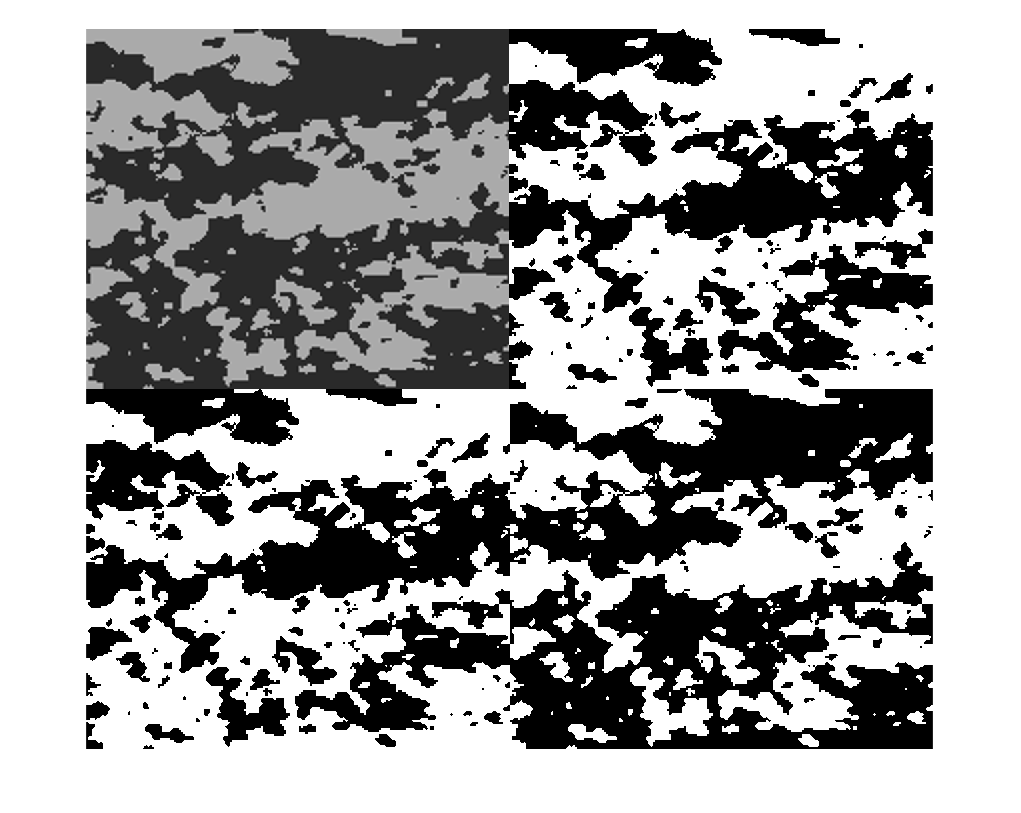

imgHsv = rgb2hsv(uint8(img*255));
imgLab = rgb2lab(uint8(img*255));
imgGray = rgb2gray(uint8(img*255));
imgYcbcr = rgb2ycbcr(uint8(img*255));

montage({imgHsv(:,:,1), imbinarize(imgLab(:,:,3)), imbinarize(imgGray), imbinarize(imgYcbcr(:,:,2))}, 'Size', [2,2])

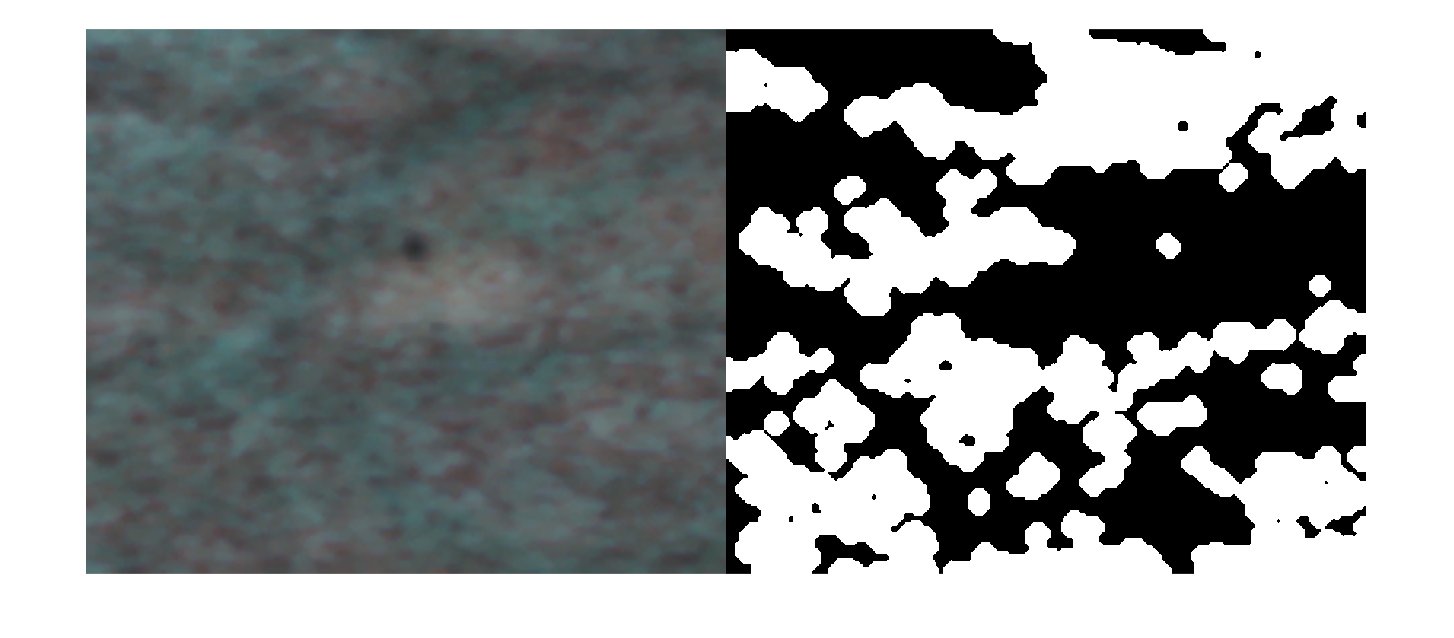

se2 = strel('disk',4);

imgErode2 = imerode(~imbinarize(imgYcbcr(:,:,2)),se2);
imgEroDil = imdilate(imgErode2, se2);

montage({adaptHistEqualRGB, imgEroDil}, 'Size', [1,2])